# A dataset of EEG signals related to upper and lower limb execution of motor and motor imagery tasks

#### by Victor Asanza:

- `Repository: `[`https://github.com/Human-Machine-Interface/OpenBCI_Classification_Example`](https://github.com/Human-Machine-Interface/OpenBCI_Classification_Example)

- `When using this code you must download the Mendeley dataset into the ``MILimbEEG`` folder: `[http://dx.doi.org/10.17632/w9xfz56txv.2](http://dx.doi.org/10.17632/w9xfz56txv.2)

- Hardware: FM=16 chanels , Cyton + Dasy , Campling Rate = 125 Hz

- Subjects: 24

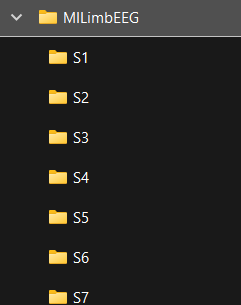

**All Labels:**

- *(Sx + Rx + Ix + _n) or (Sn + Rn + Mn + _n), example: S2R1I1_0*

- *Sx: such that x can be any number from 1 to 60.*

- *Rx: Number of times the entire experiment was repeated. Such that x can be any repetition number between 1 and 4.*

- *M: motor tasks. I: imagery tasks.*

- *1 is for ****BEO****, 2 for ****CLH****, 3 for ****CRH****, 4 for ****DLF****, 5 for ****PLF****, 6 for ****DRF****, 7 for ****PRF**** and finally 8 for ****Rest.***

- ***_n: ****Ordinal number of the task repetition. Number of times each task is repeated.*

**Relevant information:**

- `Data was collected using the following repository: `[`https://github.com/vasanza/OpenBCI`](https://github.com/vasanza/OpenBCI)

- Code for real-time detection: [https://github.com/vasanza/BCI_Motor_Imagery_Task_OpenBCI](https://github.com/vasanza/BCI_Motor_Imagery_Task_OpenBCI)

- `This dataset (MILimbEEG) was published in the following journal:: `[`https://www.sciencedirect.com/science/article/pii/S2352340923006406?via%3Dihub`](https://www.sciencedirect.com/science/article/pii/S2352340923006406?via%3Dihub)

**Pending tasks:**

- Take **stratified samples** of the class of interest (2 and 3) and the Rest class (8), from line 3 of the code

- Testing new additional features to rms from line 30 of the code

# Raw dataset preparation

clear;clc;%clear all
addpath(genpath('./src'))%functions folders
path = fullfile('./MILimbEEG/');%data folder
folders = FindFolders(path);
allData=[];

# Motor tasks of interest

**Right upper limb (RH) classification algorithms:**

- *Sx: such that x can be any number from 1 to 60.*

- *Rx: Number of times the entire experiment was repeated. Such that x can be any repetition number between 1 and 4.*

- *M: motor tasks. I: imagery tasks.*

- *3 for ****CRH****, and finally 8 for ****Rest.***

- ***_n: ****Ordinal number of the task repetition. Number of times each task is repeated.*

% List of allowed values
 allowed_values = {'M3','M8'}; pattern = 'M(\d+)'; % M: motor tasks ('AllDataRMS_motor_RH.csv')
% allowed_values = {'I3','I8'}; pattern = 'I(\d+)'; % I: imagery tasks ('AllDataRMS_imagery_RH.csv')

**Left upper limb (LH) classification algorithms:**

- *Sx: such that x can be any number from 1 to 60.*

- *Rx: Number of times the entire experiment was repeated. Such that x can be any repetition number between 1 and 4.*

- *M: motor tasks. I: imagery tasks.*

- *2 for ****CLH****, and finally 8 for ****Rest.***

- ***_n: ****Ordinal number of the task repetition. Number of times each task is repeated.*

% List of allowed values
% allowed_values = {'M2','M8'}; pattern = 'M(\d+)'; %M: motor tasks ('AllDataRMS_motor_LH.csv')
% allowed_values = {'I2','I8'}; pattern = 'I(\d+)'; % I: imagery tasks ('AllDataRMS_imagery_LH.csv')

**Right and Left upper limb (RH & LH) classification algorithms:**

- *Sx: such that x can be any number from 1 to 60.*

- *Rx: Number of times the entire experiment was repeated. Such that x can be any repetition number between 1 and 4.*

- *M: motor tasks. I: imagery tasks.*

- *2 for ****CLH**** and 3 for ****CRH****, and finally 8 for ****Rest.***

- ***_n: ****Ordinal number of the task repetition. Number of times each task is repeated.*

% List of allowed values
% allowed_values = {'M2','M3','M8'}; pattern = 'M(\d+)'; %M: motor tasks ('AllDataRMS_motor_RH_LH.csv')
% allowed_values = {'I2','I3','I8'}; pattern = 'I(\d+)'; % I: imagery tasks ('AllDataRMS_imagery_RH_LH.csv')

# Raw dataset preprocessing

#### % In this example no filtering was done, but it can be done

for i=1:length(folders)% Through all folders
    path1=fullfile(path,folders(i).name);%Select i folder
    filenames = FindCSV(path1);%List All CSV files
    for j=1:length(filenames)% Through all files
        % Extract the code using regexp
        result = regexp(filenames(j).name, pattern, 'match');
        if ~isempty(result)
            code_M = result{1}; % Get the found code, e.g., 'M1'
            if any(strcmp(code_M, allowed_values))
                data=readtable(fullfile(path1,filenames(j).name));%Select i CSV file
                dataNew=table2array(data);% Array Double
                dataNew(1,:)=[];%Delete the first row
                dataNew(:,1)=[];%Delete the first column
                DataNorm = fNormalization(dataNew);%Normalization
                Label = str2num(result{1}(2));%fLabelEEG(filenames(j).name);
                DataRMS = [rms(DataNorm) Label];%Feature extraction
                allData=[allData;DataRMS];
                
                % If you want to generate graphs with the EEG data
                %filename=strcat('./figures/',strcat(int2str(i),'_',strcat(int2str(j),strcat('_',num2str(Label)))));
                %fPlotEEG(dataNew,filename);
                %filename=strcat('./figuresNorm/',strcat(int2str(i),'_',strcat(int2str(j),strcat('_',num2str(Label)))));
                %fPlotEEG(DataNorm,filename);            
            end
        end
    end
end
%Save .CSV file with all EEG file features
csvwrite('AllDataRMS.csv',allData);

# Plot Raw EEG dataset

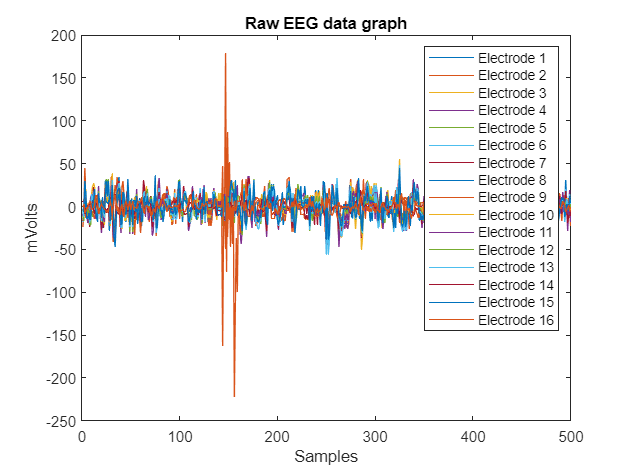

figure
plot(dataNew);xlabel('Samples');ylabel('mVolts');
title('Raw EEG data graph');
legend('Electrode 1','Electrode 2','Electrode 3','Electrode 4','Electrode 5'...
    ,'Electrode 6','Electrode 7','Electrode 8','Electrode 9','Electrode 10'...
    ,'Electrode 11','Electrode 12','Electrode 13','Electrode 14','Electrode 15','Electrode 16');

# Plot Normalization EEG dataset

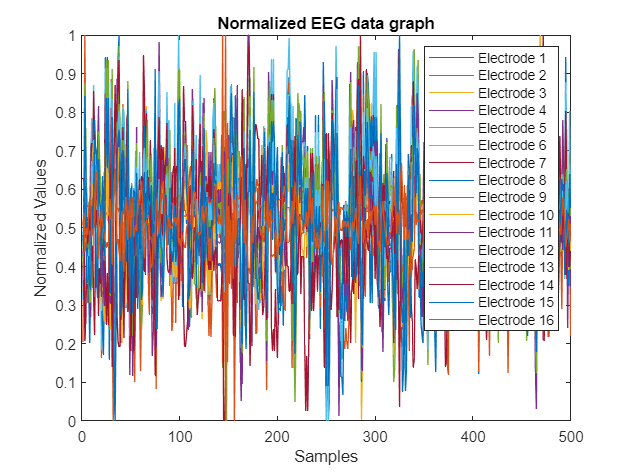

figure
plot(DataNorm);xlabel('Samples');ylabel('Normalized Values');
title('Normalized EEG data graph');
legend('Electrode 1','Electrode 2','Electrode 3','Electrode 4','Electrode 5'...
    ,'Electrode 6','Electrode 7','Electrode 8','Electrode 9','Electrode 10'...
    ,'Electrode 11','Electrode 12','Electrode 13','Electrode 14','Electrode 15','Electrode 16');

# Statistical information of rms in EEG dataset

Electrode_1 = datastats(allData(:,1))%RMS Electrode 1

Electrode_1 = struct with fields:
       num: 2161
       max: 0.8104
       min: 0.2428
      mean: 0.5194
    median: 0.5211
     range: 0.5676
       std: 0.0597


Electrode_2 = datastats(allData(:,2))%RMS Electrode 2

Electrode_2 = struct with fields:
       num: 2161
       max: 0.7611
       min: 0.2020
      mean: 0.5115
    median: 0.5154
     range: 0.5590
       std: 0.0553


Electrode_3 = datastats(allData(:,3))%RMS Electrode 3

Electrode_3 = struct with fields:
       num: 2161
       max: 0.7427
       min: 0.2967
      mean: 0.5122
    median: 0.5151
     range: 0.4460
       std: 0.0541


Electrode_4 = datastats(allData(:,4))%RMS Electrode 4

Electrode_4 = struct with fields:
       num: 2161
       max: 0.7985
       min: 0.2522
      mean: 0.5150
    median: 0.5144
     range: 0.5464
       std: 0.0585


Electrode_5 = datastats(allData(:,5))%RMS Electrode 5

Electrode_5 = struct with fields:
       num: 2161
       max: 0.7710
       min: 0.1518
      mean: 0.5219
    median: 0.5243
     range: 0.6191
       std: 0.0564


Electrode_6 = datastats(allData(:,6))%RMS Electrode 6

Electrode_6 = struct with fields:
       num: 2161
       max: 0.7624
       min: 0.2411
      mean: 0.5212
    median: 0.5235
     range: 0.5213
       std: 0.0546


Electrode_7 = datastats(allData(:,7))%RMS Electrode 7

Electrode_7 = struct with fields:
       num: 2161
       max: 0.7504
       min: 0.2926
      mean: 0.5174
    median: 0.5207
     range: 0.4579
       std: 0.0521


Electrode_8 = datastats(allData(:,8))%RMS Electrode 8

Electrode_8 = struct with fields:
       num: 2161
       max: 0.7413
       min: 0.2527
      mean: 0.5211
    median: 0.5220
     range: 0.4886
       std: 0.0532


Electrode_9 = datastats(allData(:,9))%RMS Electrode 9

Electrode_9 = struct with fields:
       num: 2161
       max: 0.8362
       min: 0.1276
      mean: 0.5196
    median: 0.5205
     range: 0.7086
       std: 0.0642


Electrode_10 = datastats(allData(:,10))%RMS Electrode 10

Electrode_10 = struct with fields:
       num: 2161
       max: 0.8807
       min: 0.1412
      mean: 0.5199
    median: 0.5209
     range: 0.7395
       std: 0.0596


Electrode_11 = datastats(allData(:,11))%RMS Electrode 11

Electrode_11 = struct with fields:
       num: 2161
       max: 0.9085
       min: 0.1898
      mean: 0.5195
    median: 0.5224
     range: 0.7186
       std: 0.0575


Electrode_12 = datastats(allData(:,12))%RMS Electrode 12

Electrode_12 = struct with fields:
       num: 2161
       max: 0.9007
       min: 0.2673
      mean: 0.5213
    median: 0.5223
     range: 0.6334
       std: 0.0557


Electrode_13 = datastats(allData(:,13))%RMS Electrode 13

Electrode_13 = struct with fields:
       num: 2161
       max: 0.9111
       min: 0.1422
      mean: 0.5220
    median: 0.5222
     range: 0.7689
       std: 0.0580


Electrode_14 = datastats(allData(:,14))%RMS Electrode 14

Electrode_14 = struct with fields:
       num: 2161
       max: 0.8704
       min: 0.1653
      mean: 0.5229
    median: 0.5236
     range: 0.7051
       std: 0.0583


Electrode_15 = datastats(allData(:,15))%RMS Electrode 15

Electrode_15 = struct with fields:
       num: 2161
       max: 0.9014
       min: 0.1609
      mean: 0.5216
    median: 0.5207
     range: 0.7405
       std: 0.0611


Electrode_16 = datastats(allData(:,16))%RMS Electrode 16

Electrode_16 = struct with fields:
       num: 2161
       max: 0.9112
       min: 0.1814
      mean: 0.5200
    median: 0.5217
     range: 0.7298
       std: 0.0624


# Feature Selection

DataFeatures=allData(:,1:16);
%corrplot(DataNorm)
R = corrcoef(DataFeatures)

R =     1.0000    0.2184    0.1772    0.1512    0.1863    0.1972    0.1848    0.1026    0.1050    0.1135    0.0689    0.0816    0.0628    0.0608    0.0378    0.0834
    0.2184    1.0000    0.3850    0.3056    0.1822    0.3665    0.2705    0.1681    0.0408    0.0471    0.0942    0.0673    0.0635    0.0947    0.0380    0.0340
    0.1772    0.3850    1.0000    0.3750    0.2039    0.3560    0.3830    0.2790    0.0295    0.0716    0.1280    0.1366    0.1132    0.1568    0.0758    0.0920
    0.1512    0.3056    0.3750    1.0000    0.2931    0.2386    0.2977    0.1980    0.0406    0.0623    0.0956    0.1624    0.0936    0.1340    0.0972    0.1088
    0.1863    0.1822    0.2039    0.2931    1.0000    0.2449    0.2574    0.1438    0.0784    0.0817    0.0918    0.0378    0.0447    0.0652    0.0601    0.1257
    0.1972    0.3665    0.3560    0.2386    0.2449    1.0000    0.3612    0.3018    0.0769    0.1268    0.2017    0.1588    0.1394    0.1698    0.1154    0.1108
    0.1848    0.2705    0.3830

# **Classification of movement in the right upper extremity (RH):**

clear;clc;%clear all
addpath(genpath('./src'))%functions folders

% Upload .CSV file with the features of all EEG files
path = fullfile('./MILimbEEG/');%data folder

%allData = fLoad_EEG_csv(path,'AllDataRMS_motor_RH.csv');
allData = fLoad_EEG_csv(path,'AllDataRMS_imagery_RH.csv');

%ToolBox
classificationLearner

# allowed_values = {'M3','M8'}; % M: motor tasks

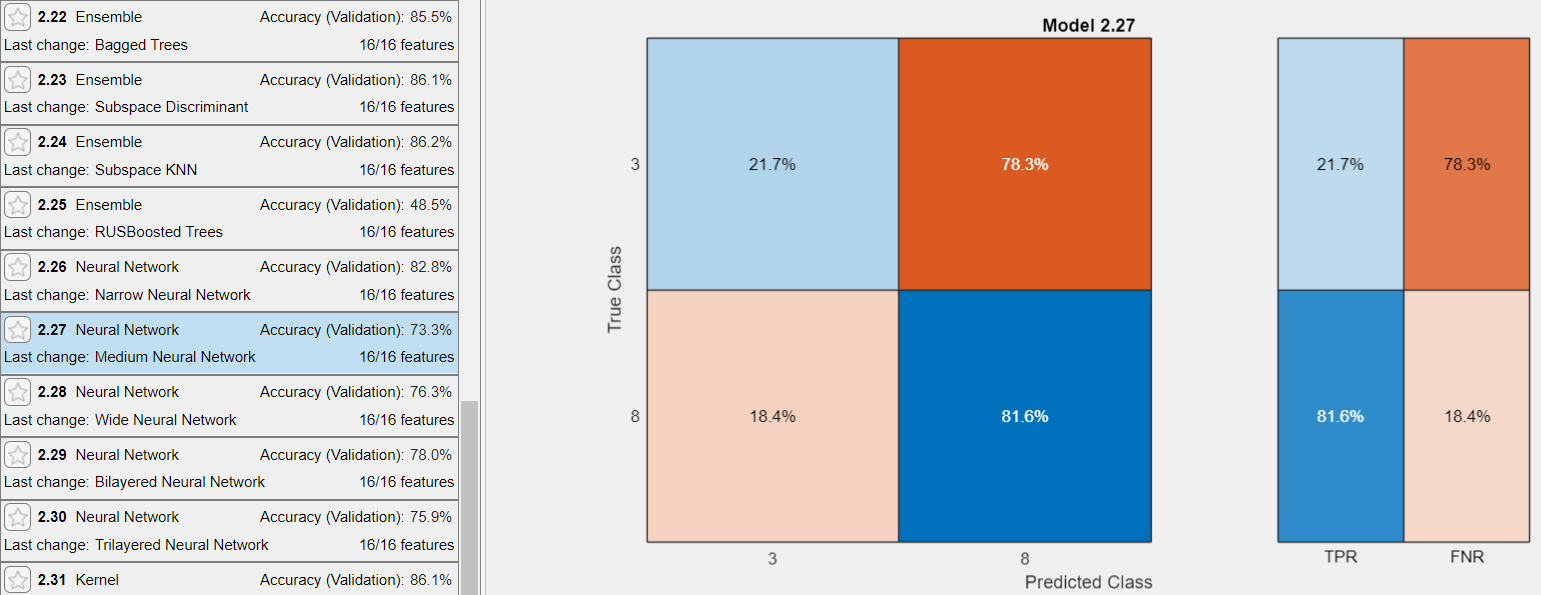

# allowed_values = {'I3','I8'}; % I: imagery tasks

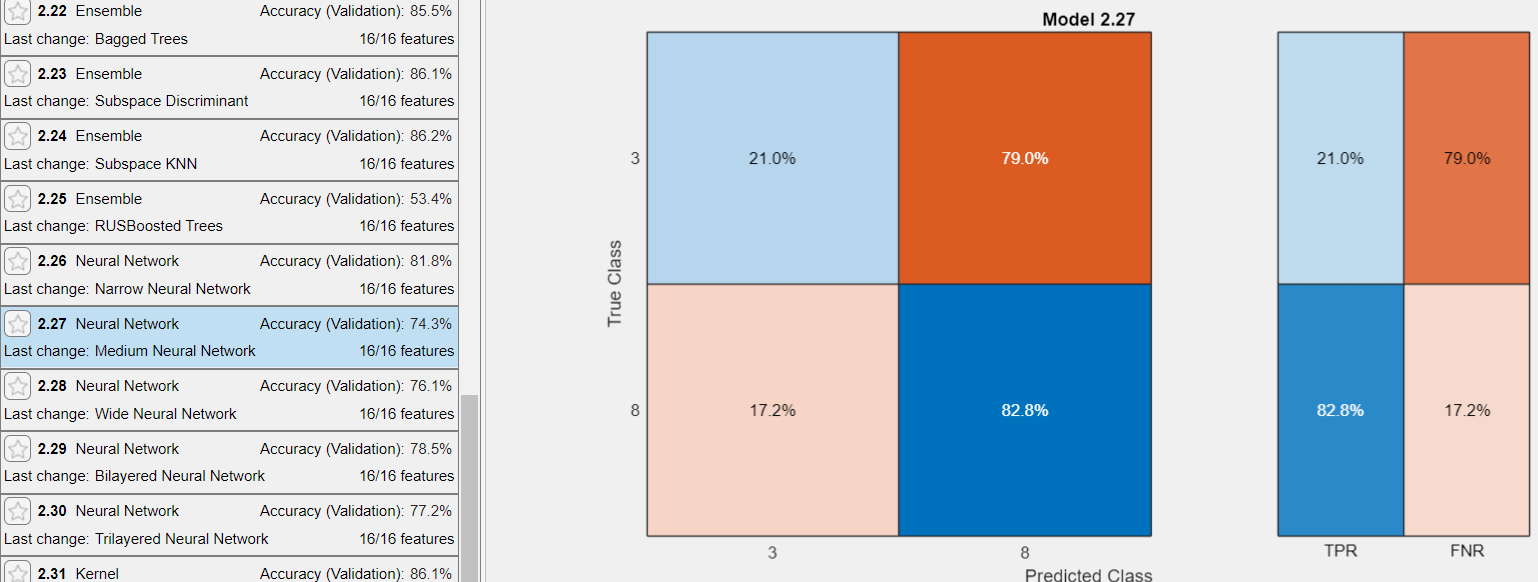

# **Classification of movement in the left upper extremity (LH):**

clear;clc;%clear all
addpath(genpath('./src'))%functions folders

% Upload .CSV file with the features of all EEG files
path = fullfile('./MILimbEEG/');%data folder

%allData = fLoad_EEG_csv(path,'AllDataRMS_motor_LH.csv');
allData = fLoad_EEG_csv(path,'AllDataRMS_imagery_LH.csv');

%ToolBox
classificationLearner

# allowed_values = {'M2','M8'}; % M: motor tasks

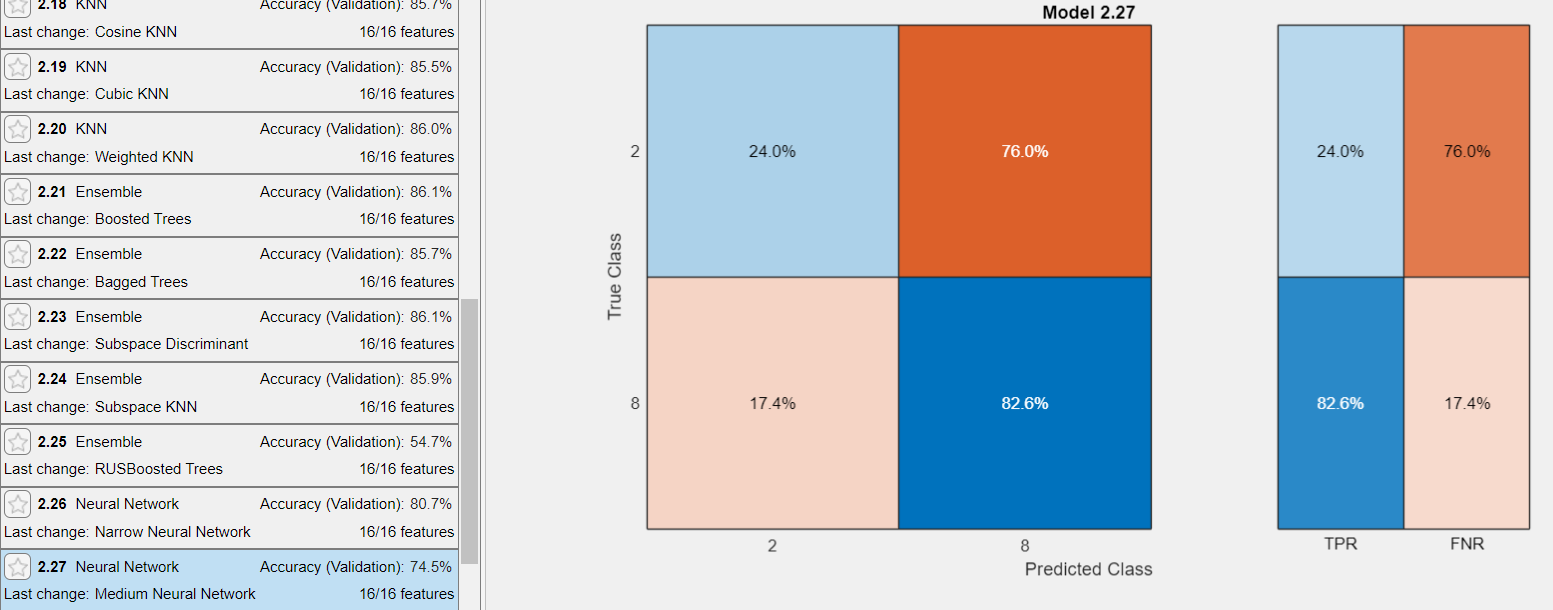

# allowed_values = {'I2','I8'}; % I: imagery tasks

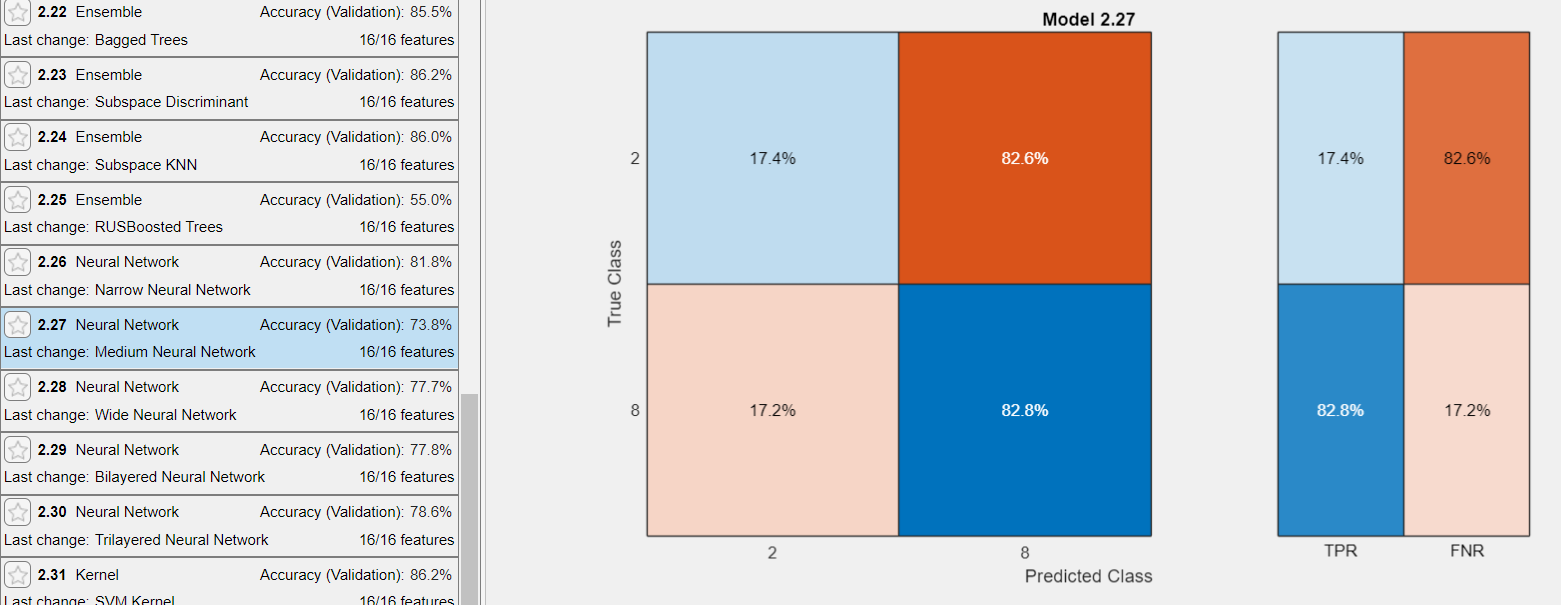

# **Classification of movement in the right and left upper extremity (RH & LH):**

clear;clc;%clear all
addpath(genpath('./src'))%functions folders

% Upload .CSV file with the features of all EEG files
path = fullfile('./MILimbEEG/');%data folder

%allData = fLoad_EEG_csv(path,'AllDataRMS_motor_RH_LH.csv');
allData = fLoad_EEG_csv(path,'AllDataRMS_imagery_RH_LH.csv');

%ToolBox
classificationLearner

# allowed_values = {'M2','M3','M8'}; % M: motor tasks

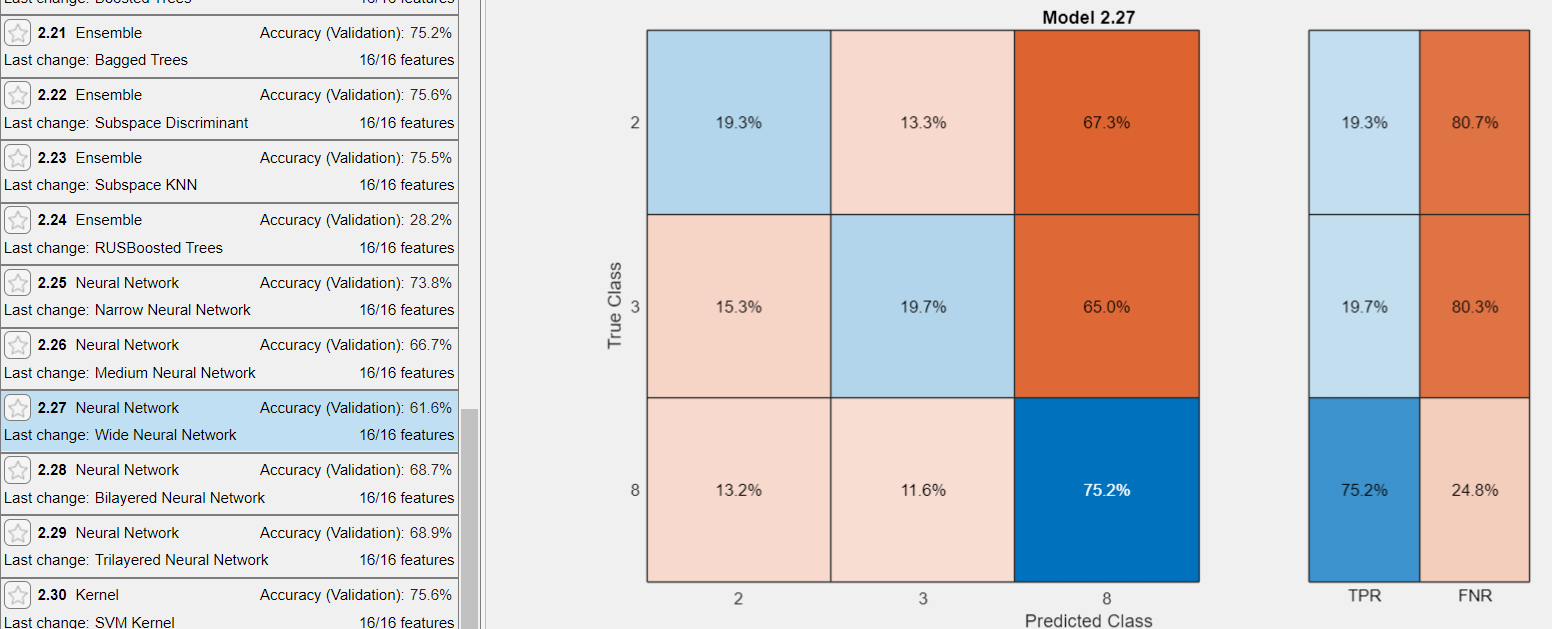

# allowed_values = {'I2','I3','I8'}; % I: imagery tasks